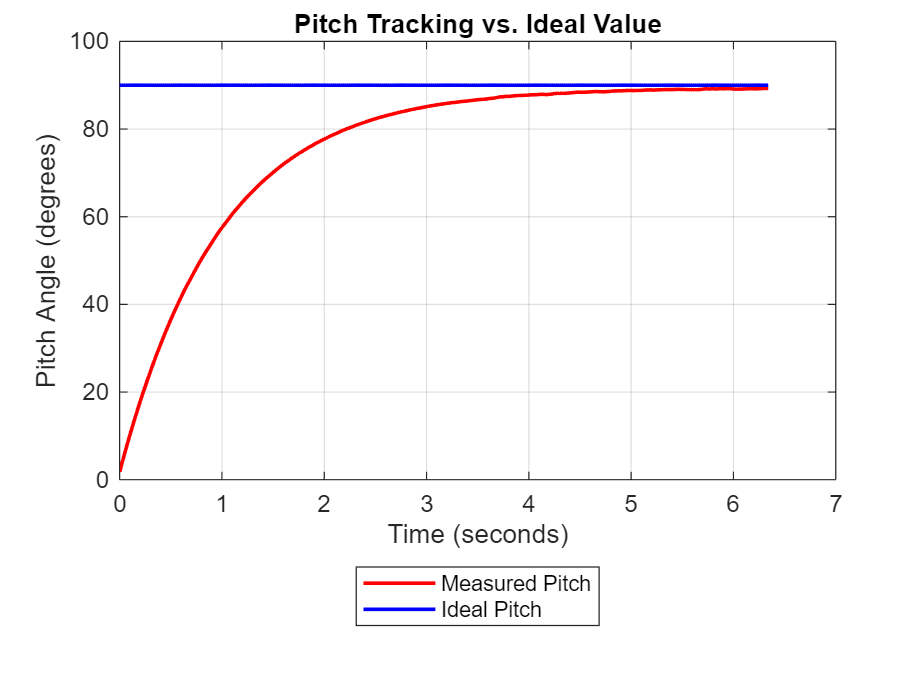

% Real (measured) and Ideal pitch angle values
real_pitch = [ ...
1.78, 3.52, 5.23, 6.89, 8.55, 10.17, 11.77, 13.33, 14.85, 16.33, ...
17.79, 19.20, 20.59, 21.96, 23.31, 24.65, 25.96, 27.24, 28.48, 29.67, ...
30.86, 32.05, 33.21, 34.34, 35.45, 36.53, 37.58, 38.62, 39.64, 40.64, ...
41.62, 42.59, 43.53, 44.42, 45.28, 46.15, 47.01, 47.87, 48.72, 49.54, ...
50.34, 51.13, 51.88, 52.61, 53.34, 54.06, 54.78, 55.49, 56.19, 56.87, ...
57.51, 58.13, 58.73, 59.35, 59.96, 60.58, 61.16, 61.69, 62.24, 62.78, ...
63.33, 63.86, 64.35, 64.84, 65.32, 65.80, 66.28, 66.75, 67.21, 67.65, ...
68.08, 68.50, 68.90, 69.30, 69.69, 70.09, 70.49, 70.88, 71.25, 71.62, ...
71.97, 72.32, 72.65, 72.98, 73.31, 73.63, 73.95, 74.26, 74.56, 74.84, ...
75.12, 75.41, 75.69, 75.97, 76.24, 76.49, 76.75, 76.99, 77.22, 77.47, ...
77.71, 77.95, 78.18, 78.41, 78.62, 78.83, 79.04, 79.25, 79.46, 79.67, ...
79.87, 80.05, 80.22, 80.39, 80.57, 80.76, 80.94, 81.11, 81.27, 81.43, ...
81.59, 81.76, 81.92, 82.07, 82.22, 82.35, 82.49, 82.64, 82.77, 82.89, ...
83.02, 83.14, 83.26, 83.38, 83.51, 83.61, 83.73, 83.85, 83.95, 84.05, ...
84.17, 84.27, 84.37, 84.47, 84.56, 84.66, 84.74, 84.83, 84.93, 85.01, ...
85.11, 85.21, 85.29, 85.37, 85.45, 85.52, 85.60, 85.68, 85.73, 85.81, ...
85.87, 85.93, 85.99, 86.05, 86.09, 86.15, 86.21, 86.27, 86.32, 86.36, ...
86.40, 86.46, 86.53, 86.59, 86.64, 86.70, 86.75, 86.78, 86.80, 86.84, ...
86.92, 86.99, 87.02, 87.07, 87.15, 87.25, 87.36, 87.34, 87.41, 87.46, ...
87.43, 87.49, 87.55, 87.57, 87.63, 87.67, 87.67, 87.69, 87.70, 87.73, ...
87.77, 87.80, 87.82, 87.83, 87.85, 87.89, 87.93, 87.93, 87.89, 87.87, ...
87.90, 87.97, 88.04, 88.11, 88.15, 88.16, 88.14, 88.14, 88.15, 88.20, ...
88.24, 88.28, 88.34, 88.39, 88.42, 88.40, 88.39, 88.40, 88.42, 88.45, ...
88.47, 88.50, 88.54, 88.56, 88.53, 88.51, 88.50, 88.50, 88.54, 88.58, ...
88.63, 88.67, 88.70, 88.71, 88.72, 88.73, 88.74, 88.77, 88.80, 88.80, ...
88.80, 88.79, 88.79, 88.80, 88.80, 88.82, 88.86, 88.89, 88.92, 88.93, ...
88.91, 88.90, 88.92, 88.94, 88.97, 88.99, 89.01, 89.01, 89.01, 89.02, ...
89.02, 89.03, 89.06, 89.08, 89.05, 89.05, 89.04, 89.02, 89.01, 89.00, ...
88.99, 88.97, 88.98, 89.00, 89.04, 89.11, 89.16, 89.19, 89.13, 89.17, ...
89.20, 89.15, 89.14, 89.18, 89.23, 89.18, 89.19, 89.22, 89.21, 89.18, ...
89.14, 89.11, 89.11, 89.12, 89.14, 89.15, 89.17, 89.19, 89.20, 89.20, ...
89.19, 89.19, 89.20, 89.21, 89.24, 89.26, 89.28, 89.28 ...
];


ideal_pitch = 90 * ones(size(real_pitch)); % constant ideal value


% Generate time vector (0.02 s per sample)
sample_interval = 0.02; % seconds
num_samples = length(real_pitch);
time = (0:num_samples-1) * sample_interval;

figure;
plot(time, real_pitch, 'r', 'LineWidth', 1.5);
hold on;
plot(time, ideal_pitch, 'b-', 'LineWidth', 1.5);
legend('Measured Pitch', 'Ideal Pitch', 'Location', 'southoutside');

xlabel('Time (seconds)');
ylabel('Pitch Angle (degrees)');
title('Pitch Tracking vs. Ideal Value');
ylim([0 100]); % Set y-axis from 0 to 100
grid on;